%%Reflectance model (April 29th, 2024)
%%3. Outline of the method
%%: phase retardation of light of wavelength λ
%%***** modify
%%Step 1: Evaluate          and    

lambda=350:1:750;

n_b=1.7;
d_b=15;
n_a=1.3;
d_a=(n_b*d_b)/n_a;

phi=(2*pi./lambda)*n_b*d_b;

r=(n_b-n_a)/(n_b+n_a);

if (cos(phi)).^2 < r^2
disp("(a)")
else
disp("(b)")
end

(b)


%%Step 2: Choose your case ((a) or (b))
%%(a) When                :             (35) where 
rho=-r.*exp(-1i.*phi).*( (1-exp(-2*1i.*phi))./(1-(r.^2).*exp(-2*1i.*phi)) );

tau=( (1-r.^2).*exp(-2*1i.*phi) )./ ( (1-exp(-2*1i.*phi))./(1-(r.^2).*exp(-2*1i.*phi)) );

%% Expressions for mu are obtained by solving the quadratic equation (both are complex)
a=(1+tau.^2-rho.^2)./tau;
mu_1=(a+sqrt(a.^2+4))./2;
mu_2=(a-sqrt(a.^2+4))./2;

p=1;

R_mod=1./(1+( (4.*((mu_1.^p).^2).*(r.^2-(cos(phi)).^2))./((r.^2).*(1-(mu_1.^p).^2).^2) ));
R_mod2=1./(1+( (4.*((mu_1.^(p+1)).^2).*(r.^2-(cos(phi)).^2))./((r.^2).*(1-(mu_1.^(p+1)).^2).^2) ));
R_mod3=1./(1+( (4.*((mu_1.^(p+2)).^2).*(r.^2-(cos(phi)).^2))./((r.^2).*(1-(mu_1.^(p+2)).^2).^2) ));
R_mod4=1./(1+( (4.*((mu_1.^(p+3)).^2).*(r.^2-(cos(phi)).^2))./((r.^2).*(1-(mu_1.^(p+3)).^2).^2) ));

plot(lambda,R_mod)

hold on
plot(lambda,R_mod2)

hold on
plot(lambda,R_mod3)

hold on
plot(lambda,R_mod4)

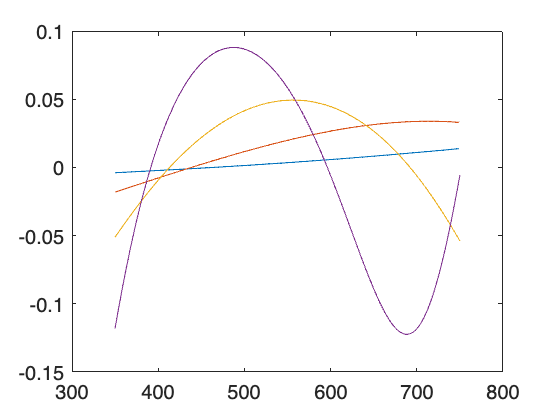

hold off


%xlabel('Wavelength (nm)')
%ylabel('Reflectance')
%legend('p=1','p=2','p=3','p=4')

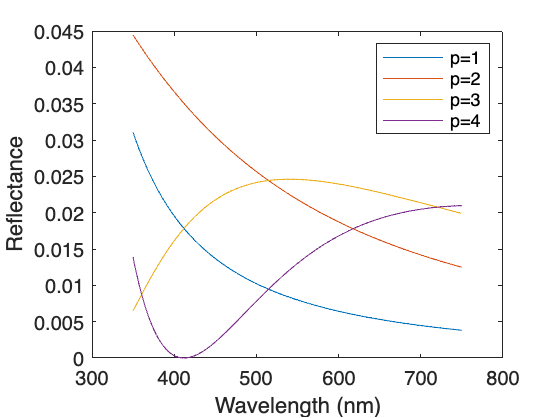

%%(b)
%%(b) When                :            (39) where               (25)
theta=acos( ( cos(2.*phi)-r^2 )./(1-r^2) );
p=1;

R=(1./ (1+ ( (cos(2.*phi)).^2-r.^2 )./((sin(p.*theta)).^2.*(r.^2)) ));
R_2=(1./ (1+ ( (cos(2.*phi)).^2-r.^2 )./((sin((p+1).*theta)).^2.*(r.^2)) ));
R_3=(1./ (1+ ( (cos(2.*phi)).^2-r.^2 )./((sin((p+2).*theta)).^2.*(r.^2)) ));
R_4=(1./ (1+ ( (cos(2.*phi)).^2-r.^2 )./((sin((p+3).*theta)).^2.*(r.^2)) ));

plot(lambda,R)
hold on
plot(lambda,R_2)
hold on
plot(lambda,R_3)
hold on
plot(lambda,R_4)
hold off

xlabel('Wavelength (nm)')
ylabel('Reflectance')
legend('p=1','p=2','p=3','p=4')

%%4.5. Amplitude reflection coefficient of the whole stack
%(30)
%%since                 then we know that
%%(28)
%%(24)
%%(25)
lambda=350:1:750;

n_b=1.6;
d_b=18;
n_a=1.2;
d_a=(n_b*d_b)/n_a;

phi=(2*pi./lambda)*n_b*d_b;

r=(n_b-n_a)/(n_b+n_a);

theta=acos( ( cos(2.*phi)-r^2 )/(1-r^2) );
p=1;

h_2=((cos(phi))./r).*(1 + sqrt(1-((r.^2)./(cos(phi).^2))));
h_1=((cos(phi))./r).*(1 - sqrt(1-((r.^2)./(cos(phi).^2))));

mu=exp(1i.*theta);

m=mu.^p;
m_2=mu.^(p+1);
m_3=mu.^(p+2);
m_4=mu.^(p+3);

R=(1-m.^2)./( 0.5.*(h_1+h_2).*(1-m.^2) -0.5.*(h_1-h_2).*(1-m.^2));
R_2=(1-m_2.^2)./( 0.5.*(h_1+h_2).*(1-m_2.^2) -0.5.*(h_1-h_2).*(1-m_2.^2));
R_3=(1-m_3.^2)./( 0.5.*(h_1+h_2).*(1-m_3.^2) -0.5.*(h_1-h_2).*(1-m_3.^2));
R_4=(1-m_4.^2)./( 0.5.*(h_1+h_2).*(1-m_4.^2) -0.5.*(h_1-h_2).*(1-m_4.^2));

R_mod=R.*conj(R)

R_mod =     0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0064    0.0064    0.0064    0.0064    0.0064    0.0064    0.0064    0.0064


R_mod2=R_2.*conj(R_2)

R_mod2 =     0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0064    0.0064    0.0064    0.0064    0.0064    0.0064    0.0064    0.0064


R_mod3=R_3.*conj(R_3)

R_mod3 =     0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0064    0.0064    0.0064    0.0064    0.0064    0.0064    0.0064    0.0064


R_mod4=R_4.*conj(R_4)

R_mod4 =     0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0068    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0067    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0066    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0065    0.0064    0.0064    0.0064    0.0064    0.0064    0.0064    0.0064    0.0064


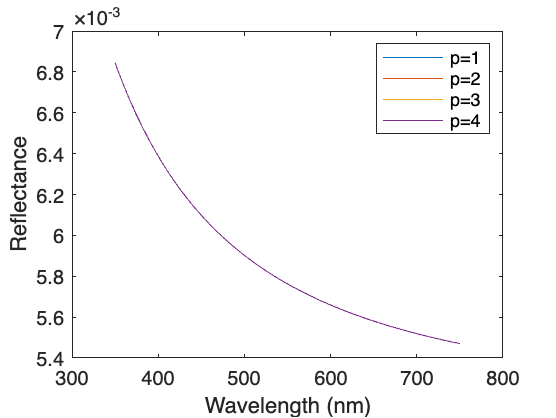


plot(lambda,R_mod)
hold on
plot(lambda,R_mod2)
hold on
plot(lambda,R_mod3)
hold on
plot(lambda,R_mod4)
hold off

xlabel('Wavelength (nm)')
ylabel('Reflectance')
legend('p=1','p=2','p=3','p=4')

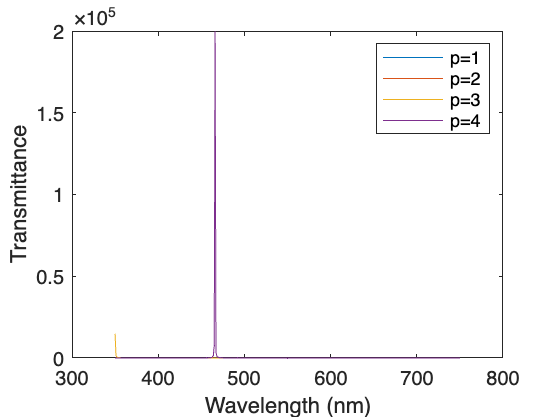


T=((h_2-h_1).*m)./( 0.5.*(h_1+h_2).*(1-m.^2) -0.5.*(h_1-h_2).*(1-m.^2));
T_2=((h_2-h_1).*m_2)./( 0.5.*(h_1+h_2).*(1-m_2.^2) -0.5.*(h_1-h_2).*(1-m_2.^2));
T_3=((h_2-h_1).*m_3)./( 0.5.*(h_1+h_2).*(1-m_3.^2) -0.5.*(h_1-h_2).*(1-m_3.^2));
T_4=((h_2-h_1).*m_4)./( 0.5.*(h_1+h_2).*(1-m_4.^2) -0.5.*(h_1-h_2).*(1-m_4.^2));

T_mod=T.*conj(T);
T_mod2=T_2.*conj(T_2);
T_mod3=T_3.*conj(T_3);
T_mod4=T_4.*conj(T_4);

plot(lambda,T_mod)
hold on
plot(lambda,T_mod2)
hold on
plot(lambda,T_mod3)
hold on
plot(lambda,T_mod4)
hold off

xlabel('Wavelength (nm)')
ylabel('Transmittance')
legend('p=1','p=2','p=3','p=4')

%%4.6. Intensity reflection coefficient of the whole stack
%%(b)                
%%(39)
%%(25)
lambda=350:1:750;

n_b=1.8;
d_b=220;
n_a=1.33;
d_a=(n_b*d_b)/n_a;

phi=(2*pi./lambda)*n_b*d_b;

r=(n_b-n_a)/(n_b+n_a);


theta=acos( ( cos(2.*phi)-r^2 )/(1-r^2) );
p=1;

R=(1./(1+((cos(phi)).^2)-r^2)./((r^2).*(sin(p.*theta)).^2));
R_2=(1./(1+((cos(phi)).^2)-r^2)./((r^2).*(sin((p+1).*theta)).^2));
R_3=(1./(1+((cos(phi)).^2)-r^2)./((r^2).*(sin((p+2).*theta)).^2));
R_4=(1./(1+((cos(phi)).^2)-r^2)./((r^2).*(sin((p+3).*theta)).^2));

plot(lambda,R)

hold on
plot(lambda,R_2)

hold on
plot(lambda,R_3)

hold on
plot(lambda,R_4)

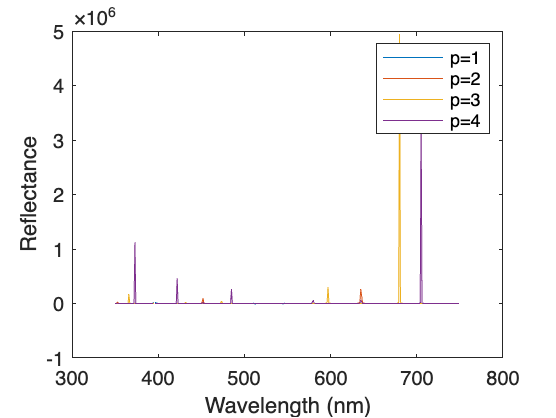

hold off

xlabel('Wavelength (nm)')
ylabel('Reflectance')
legend('p=1','p=2','p=3','p=4')

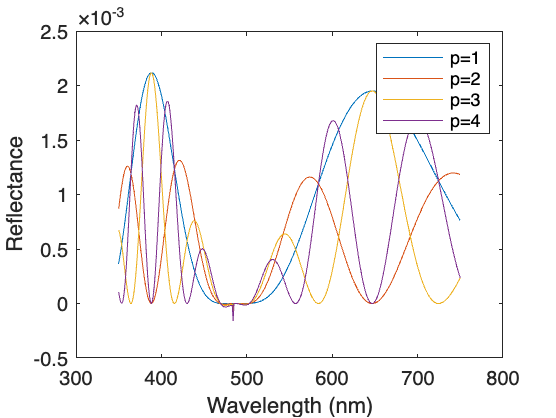


%%5.1. Optical thicknesses of plates and spaces not equal

lambda=350:1:750;

n_b=1.8;
d_b=100;
n_a=1.33;
d_a=230;

phi_a=(2*pi./(lambda))*n_a*d_a;
phi_b=(2*pi./(lambda))*n_b*d_b;

r=(n_b-n_a)/(n_b+n_a);

k=-( sin(phi_a+phi_b)-r^2.*sin(phi_a-phi_b) )./(2.*(r^2).*(sin(phi_a+phi_b)).^2);
p=1;

R=[];
R_2=[];
R_3=[];
R_4=[];
for j=1:length(lambda)
theta1=acos( ( cos(phi_a(j)+phi_b(j))-r^2.*cos(phi_a(j)-phi_b(j)) )/(1-r^2) );
t=theta1;

R(j)=(1/( 1+(-1+k(j)^2)*((csc(p*t))^2) ));
R_2(j)=(1/( 1+(-1+k(j)^2)*((csc((p+1)*t))^2) ));
R_3(j)=(1/( 1+(-1+k(j)^2)*((csc((p+2)*t))^2) ));
R_4(j)=(1/( 1+(-1+k(j)^2)*((csc((p+3)*t))^2) ));
end

R_mod=R.*conj(R);
R_mod2=R_2.*conj(R_2);
R_mod3=R_3.*conj(R_3);
R_mod4=R_4.*conj(R_4);

plot(lambda,R)
hold on
plot(lambda,R_2)
hold on
plot(lambda,R_3)
hold on
plot(lambda,R_4)
hold off

xlabel('Wavelength (nm)')
ylabel('Reflectance')
legend('p=1','p=2','p=3','p=4')


%%Additional (attempt to create a non ideal transmittance model)
%(31): transmission coefficient of the whole stack derived by the transmitted (    ) and incident amplitude (    ).
%%(Eq. before 47): this is the expression when the pptical thicknesses of plates and spaces are not equal (            )
%%(49): parameter derived from θ.
%%: obtained from the μ expression for the 'complex' case (                ).
% Calculation of the wavelength-dependent refractive index
lambda=0.350:0.001:0.750;
n_lambda=[];
n_air=1;

A=1.52266;
B=0.000733;
C=-0.0000482;

for j=1:length(lambda)
n_lambda(j)=A+(B/(lambda(j)^2))+(C/(lambda(j)^4));
end

lambda=350:1:750

lambda =    350   351   352   353   354   355   356   357   358   359   360   361   362   363   364   365   366   367   368   369   370   371   372   373   374   375   376   377   378   379   380   381   382   383   384   385   386   387   388   389   390   391   392   393   394   395   396   397   398   399


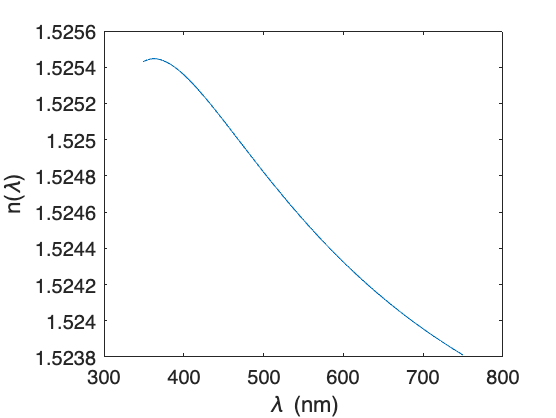


plot(lambda,n_lambda)
xlabel("\lambda (nm)")
ylabel("n(\lambda)")


%Calculation of the refractive indices for each plane
FF=180/890;
n_a=sqrt((FF*(n_lambda.^2))+((1-FF)*1^2))

n_a =     1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262    1.1262


n_b=(0.83*1)+(0.17*n_lambda)

n_b =     1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893    1.0893


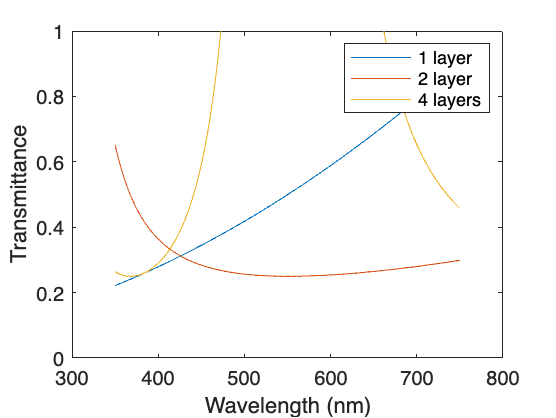


% Incidence angle for each plane
%v_a=deg2rad(64.1581); %% Numerical aperture of the condenser
v_a=deg2rad(64.1581);
v_b=asin( (sin(v_a)*n_a)./(n_b) );
v_bair=asin( (sin(v_a)*n_a) );

d_b=210;
d_a=110;

phi_a=(2.*pi./lambda).*n_a.*d_a.*cos(v_a);
phi_b=(2.*pi./lambda).*n_b.*d_b.*cos(v_b);
phi_bair=(2.*pi./lambda).*d_b.*cos(v_bair);

r=(n_b-n_a)./(n_b+n_a);
rair=(1-n_a)./(1+n_a);

%theta=acos( ( cos(phi_a+phi_b)-r.^2.*cos(phi_a-phi_b) )/(1-r.^2) );
p=1;

k_dash= -(cos(phi_a+phi_b)-r.^2.*cos(phi_a-phi_b) )./(1-r.^2);

h_1=-( sin(phi_a+phi_b)-r.^2.*(sin(phi_a-phi_b)) + 1i*(1-r.^2).*sqrt(-1+k_dash.^2) )./(2.*r.*sin(phi_b));
h_2=-( sin(phi_a+phi_b)-r.^2.*(sin(phi_a-phi_b)) - 1i*(1-r.^2).*sqrt(-1+k_dash.^2) )./(2.*r.*sin(phi_b));
h_2air=-( sin(phi_a+phi_bair)-r.^2.*(sin(phi_a-phi_bair)) - 1i*(1-r.^2).*sqrt(-1+k_dash.^2) )./(2.*r.*sin(phi_bair));

theta=acos( ( cos(phi_a+phi_b)-r.^2.*cos(phi_a-phi_b) )./(1-r.^2) );
theta_air=acos( ( cos(phi_a+phi_bair)-rair.^2.*cos(phi_a-phi_bair) )./(1-rair.^2) );

mair=sqrt(exp(-2.*1i.*p.*theta_air));
m=sqrt(exp(-2.*1i.*p.*theta));
m_2=sqrt(exp(-2.*1i.*(p+1).*theta));
m_3=sqrt(exp(-2.*1i.*(p+2).*theta));
m_4=sqrt(exp(-2.*1i.*(p+3).*theta));

T_air=((h_2air-h_1).*mair)./( 0.5.*(h_1+h_2air).*(1-mair.^2) -0.5.*(h_1-h_2air).*(1-mair.^2));
T=((h_2-h_1).*m)./( 0.5.*(h_1+h_2).*(1-m.^2) -0.5.*(h_1-h_2).*(1-m.^2));
T_2=((h_2-h_1).*m_2)./( 0.5.*(h_1+h_2).*(1-m_2.^2) -0.5.*(h_1-h_2).*(1-m_2.^2));
T_3=((h_2-h_1).*m_3)./( 0.5.*(h_1+h_2).*(1-m_3.^2) -0.5.*(h_1-h_2).*(1-m_3.^2));
T_4=((h_2-h_1).*m_4)./( 0.5.*(h_1+h_2).*(1-m_4.^2) -0.5.*(h_1-h_2).*(1-m_4.^2));

T_mod_air=T_air.*conj(T_air);
T_mod=T.*conj(T);
T_mod2=T_2.*conj(T_2);
T_mod3=T_3.*conj(T_3);
T_mod4=T_4.*conj(T_4);

plot(lambda,T_mod_air)
hold on
plot(lambda,T_mod)
hold on
plot(lambda,T_mod2)
hold on
%plot(lambda,T_mod3)
hold on
%plot(lambda,T_mod4)
hold off

ylim([0 1]);
xlabel('Wavelength (nm)')
ylabel('Transmittance')
legend('1 layer','2 layer','4 layers')